## 5. Image binarization

Complete the script "exercise5.m" to implement the following steps: The binarization $B_I \left(x,y\right)$of an image $I\left(x,y\right)$ from a threshold ($\mathrm{Th}$) consists in turning the image into a binary image (of 0s and 1s) that will depend on whether the level of the pixel intensity of the original image is above or below a threshold.


$$B_I \left(x,y\right)=\left\lbrace \begin{array}{cc}
0 & \forall \left(x,y\right):I\left(x,y\right)<\mathrm{Th}\\
1 & \forall \left(x,y\right):I\left(x,y\right)\ge \mathrm{Th}
\end{array}\right.$$


Given the image car_gray.jpg, create the function thresholdImg() which implements the following points:

CAR = imread('images/car_gray.jpg');

1. Create the binary version of the original image by a threshold value of 20. What does it happen if we use different threshold values (30, 150, 255)? Why?

Implementation code in the Defined Function section at the end of the report. 

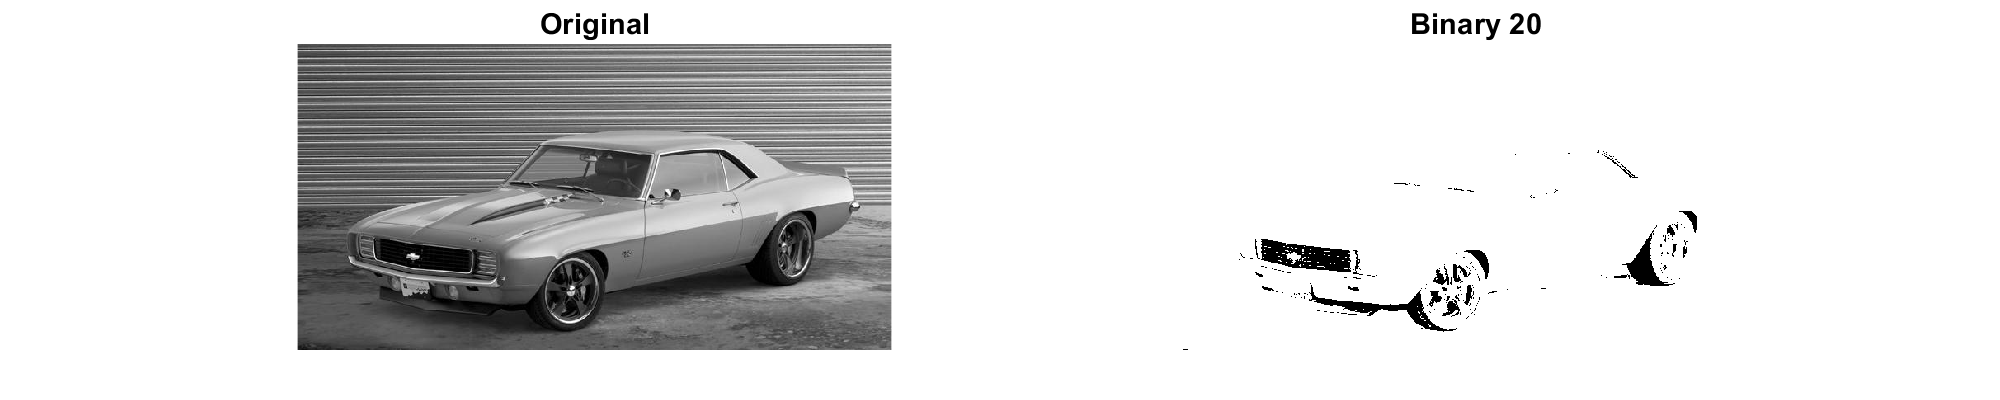

% binary with threshold 20
bin20 = thresholdImg(CAR, 20);
% threshold of 30, 150, 255
bin30 = thresholdImg(CAR, 30);
bin150 = thresholdImg(CAR, 150);
bin255 = thresholdImg(CAR, 255);

% plot the different images
set(gcf,'Position',[0 0 1000 200])
subplot(1,2,1), imshow(CAR), title("Original"), ...
subplot(1,2,2), imshow(bin20*255), title("Binary 20");

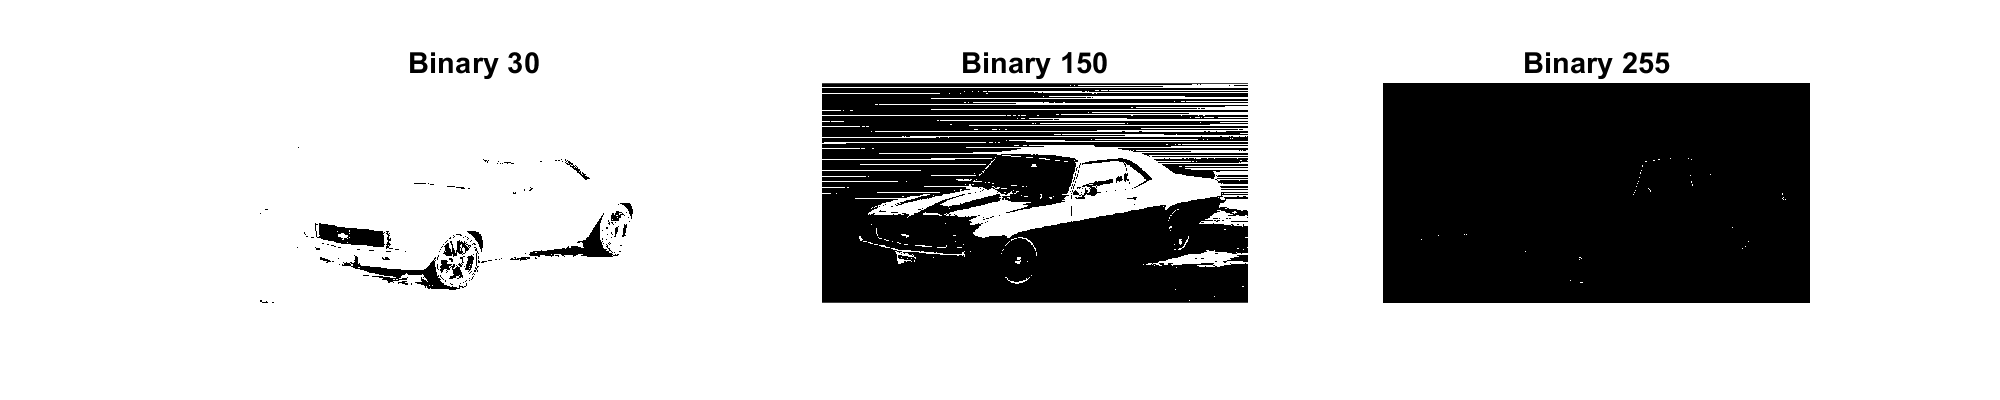

subplot(1,3,1), imshow(bin30*255), title("Binary 30"), ...
subplot(1,3,2), imshow(bin150*255), title("Binary 150"), ...
subplot(1,3,3), imshow(bin255*255), title("Binary 255");

We observe that for a low threshold the image is very bright and hard to see detail. This is because a high portion of the image is being converted to ones.

While that for a medium threshold, there is a good contrast to see the edges of the car and detail. This is because there is a balanced proportion of elements being binarized to zero with those being binarized to 1.

For a high threshold, the opposite effect of a low threshold is observed. The image is very dark and it is hard to see detail of the image. This is because a large portion of the inormation of the image is being binarized to 0.     

2. Visualize and save the image of threshold 150 as car_binary.jpg.

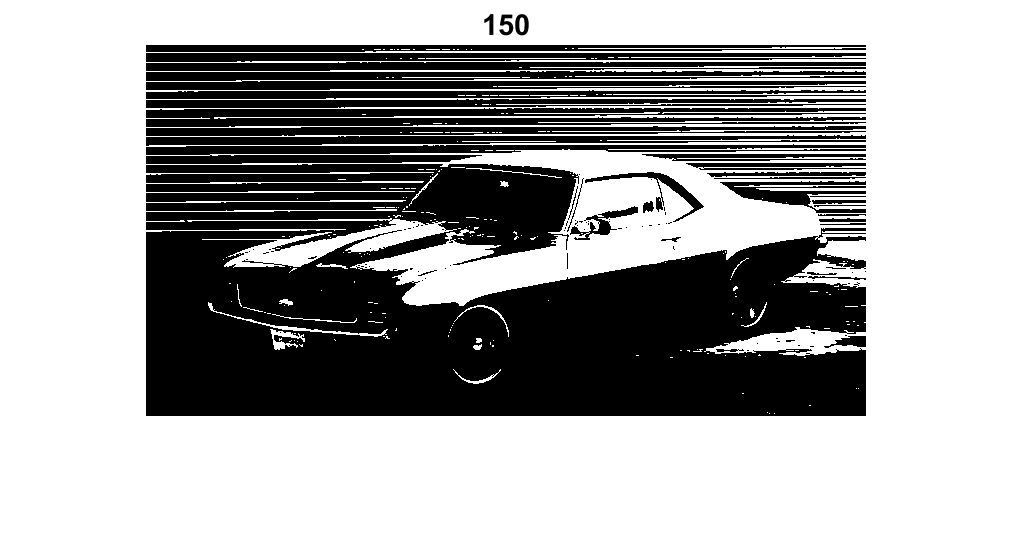

subplot(1,1,1), imshow(bin150*255), title("150");

imwrite(bin150*255, 'car_binary.jpg');

3. What will happen if you multiply the original image by the binary image?

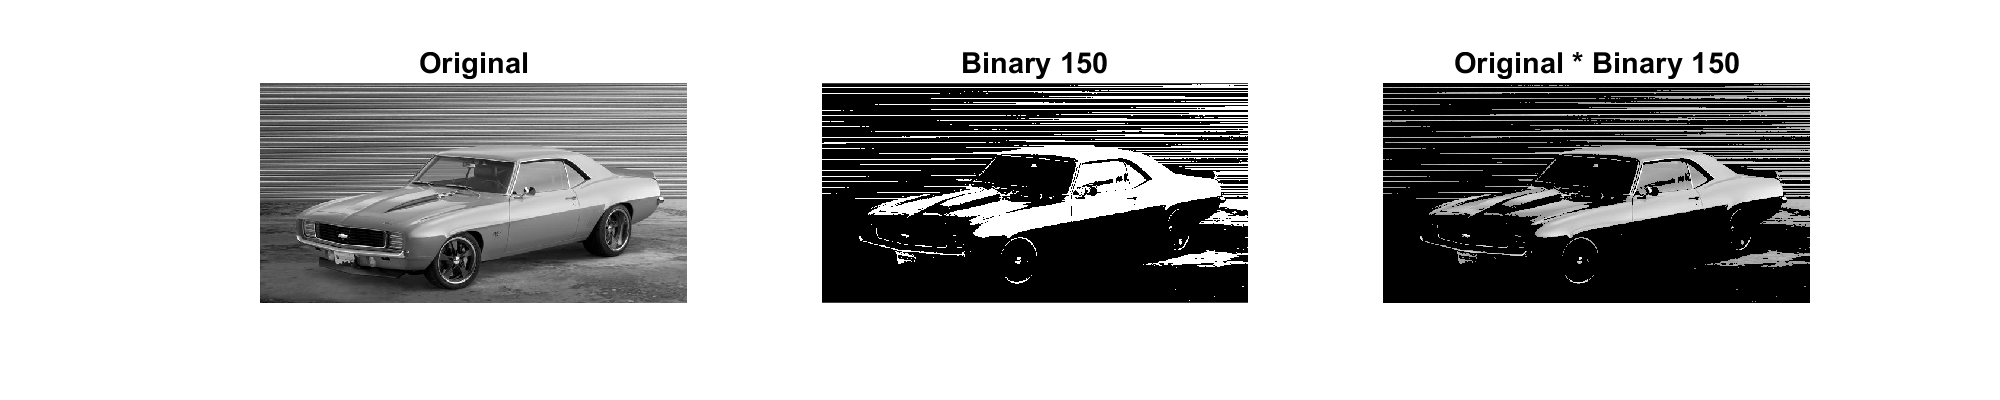

set(gcf,'Position',[0 0 1000 200]);
subplot(1,3,1), imshow(CAR), title("Original"), ...
subplot(1,3,2), imshow(bin150*255), title("Binary 150"), ...
subplot(1,3,3), imshow(CAR .* bin150), title("Original * Binary 150");

The resulting image contains the original intensity in the areas where the binary image has the value of 1 while it is black in the areas of with value 0.

4. What will happen if you multiply the original image with the inverted binary image?

We consider the inverted image as the complementary image. 

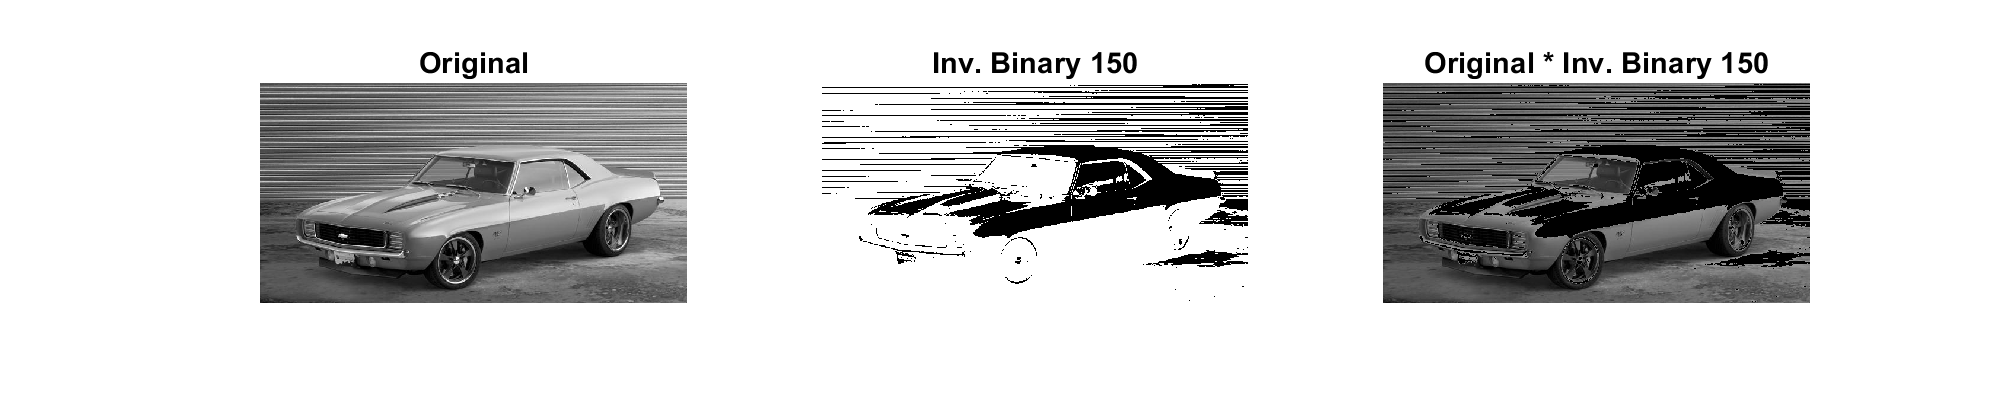

subplot(1,3,1), imshow(CAR), title("Original"), ...
subplot(1,3,2), imshow(not(bin150)), title("Inv. Binary 150"), ...
subplot(1,3,3), imshow(CAR .* uint8(not(bin150))), ...
title("Original * Inv. Binary 150");

Inverting the binary image makes the resulting image to be black where it was previously white. What was previously black, now it has the intensity from the original image. It is the same effect of the previous question but inverted.

## Defined Functions

function binImg = thresholdImg(img, thresh)
%THRESHOLDIMG Convert Gray Image into Binary Image
%    Transform the image (img) into a binary image (of 0s and 1s) that will 
%    depend on  whether the level of the pixel intensity of the original image 
%    is above or below a threshold (tresh). 
%    The result type is uint8 for better compatibility with gray images.
    binImg = uint8(img >= thresh);
end